%Lab 2

R1.a)

M=512;
n=0:(M-1);
w0=4.6*2*pi/M;

x=5*cos(w0*n+1)+2*cos(2*w0*n+2)+3*cos(5*w0*n+3);

R1.b)

We can observe a periodic signal, made of cosines. Additionally we can see that we have a max amplitude of almost 10 and a min amplitude of about -7

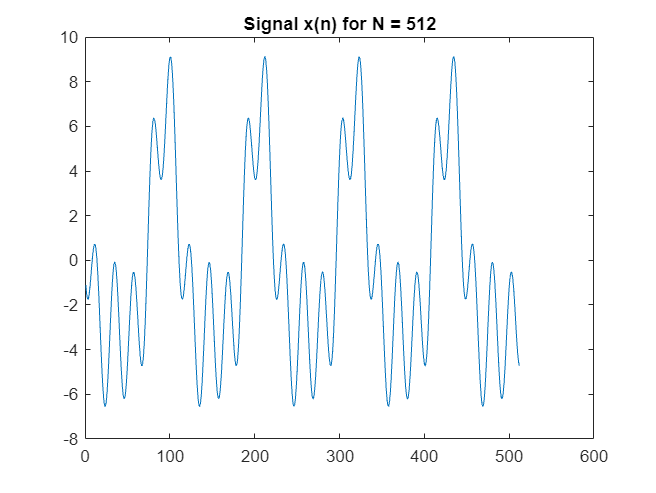

plot(x);
title('Signal x(n) for N = 512');

R1.c)

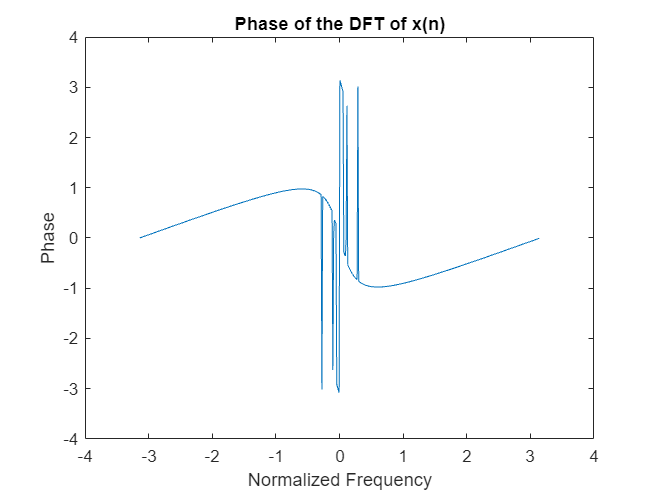

x_FT=fft(x,512); 
Sampling_Freq=2*pi/(length(x_FT)-1);
f=-pi:Sampling_Freq:pi;

x_phase=angle(x_FT);

x_abs = abs(x_FT);


% Phase plot

plot(f,fftshift(x_phase));
ylabel('Phase')
xlabel('Normalized Frequency')
title('Phase of the DFT of x(n)')

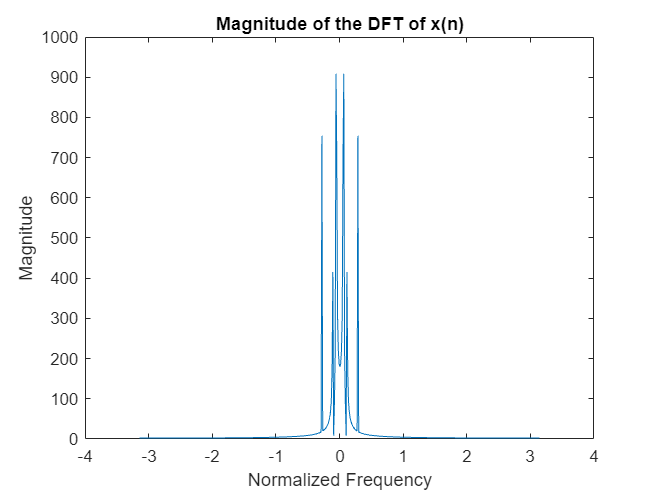


%Missing Comemnt about the phase

% Magnitude plot
plot(f,fftshift(x_abs));
ylabel('Magnitude')
xlabel('Normalized Frequency')
title('Magnitude of the DFT of x(n)')


%There are predominant low (close to 10) 
%and high (close to 500) frequencies in x(n) 

R1.d)

%3 largest peaks of the magnitude
[peaks,index] = maxk(x_abs, 3);
peaks

peaks =   908.6356  908.6356  754.1891


peaks_phase = x_phase(index)

peaks_phase =    -0.2767    0.2767    3.0157


index

index =      6   508    24


f(index)

ans =    -3.0801    3.0924   -2.8588


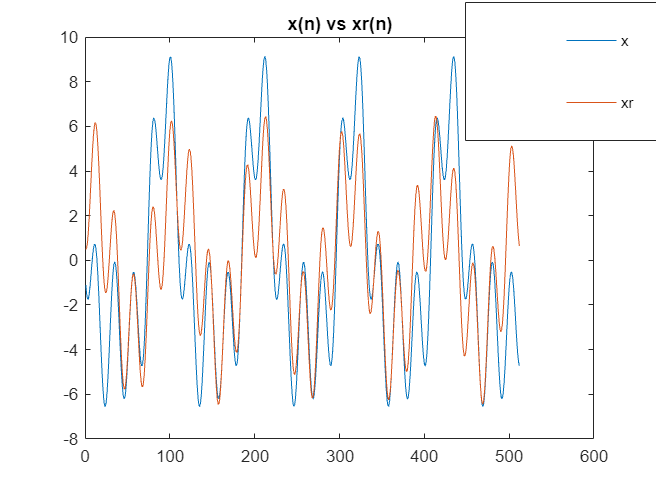

%the frequency is given by the index of the peaks

rec_x = zeros(size(x));
rec_x(index) = x_FT(index);
rec_x(512-index+2) = conj(x_FT(index));
xr = ifft(rec_x,512);

plot(x,'DisplayName','x');
hold on
plot(xr,'DisplayName','xr');
title('x(n) vs xr(n)');
hold off

legend("Position", [0.72226,0.72433,0.38557,0.26275]);

lgd = legend;

R1.e)

We can see that the signals look somewhat a like, however

there are some clear differences. 

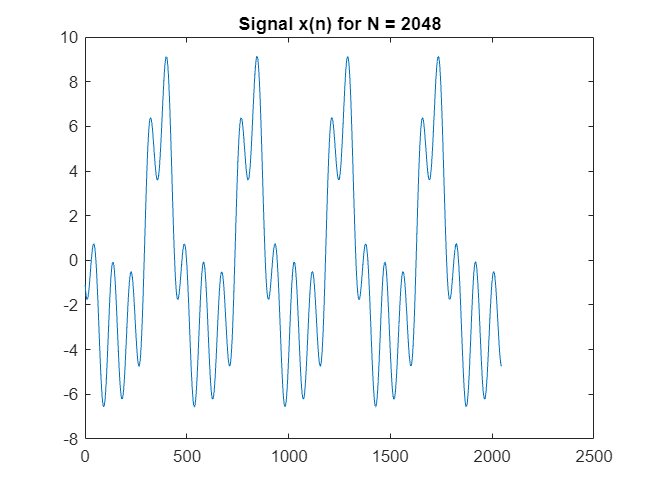

%R1.a and R1.b
M=2048;
n=0:(M-1);
w0=4.6*2*pi/M;
x2=5*cos(w0*n+1)+2*cos(2*w0*n+2)+3*cos(5*w0*n+3);
plot(x2);
title('Signal x(n) for N = 2048');

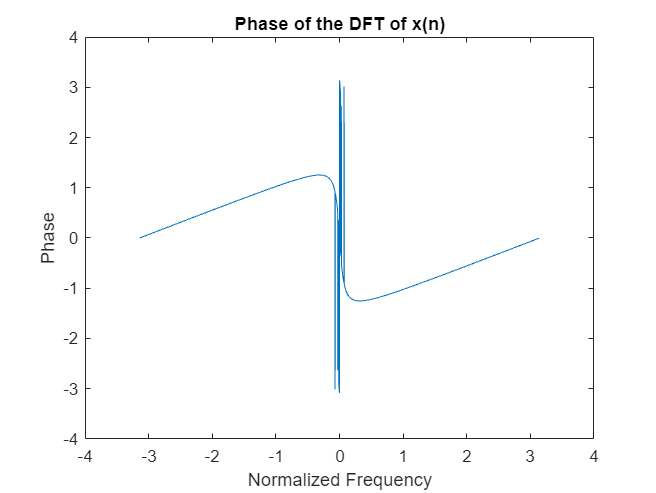


%R1.c
x_FT=fft(x2,2048);
Sampling_Freq=2*pi/(length(x_FT)-1);
f=-pi:Sampling_Freq:pi;

x_phase=angle(x_FT);
x_abs = abs(x_FT);
% Phase plot
plot(f,fftshift(x_phase));
ylabel('Phase')
xlabel('Normalized Frequency')
title('Phase of the DFT of x(n)')

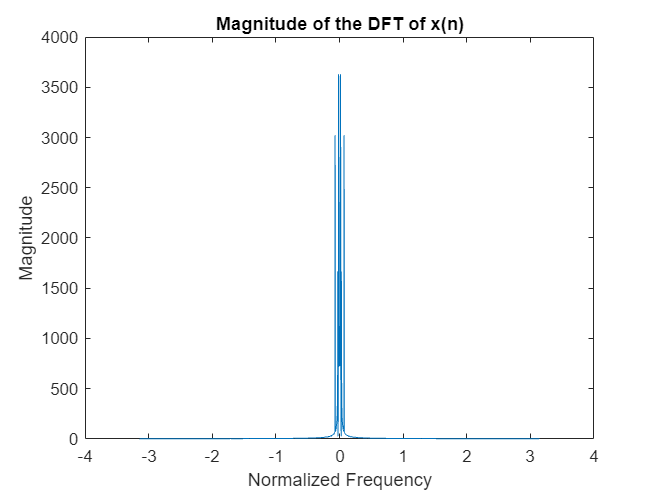

%Missing comment 
% Magnitude plot
plot(f,fftshift(x_abs));
ylabel('Magnitude')
xlabel('Normalized Frequency')
title('Magnitude of the DFT of x(n)')

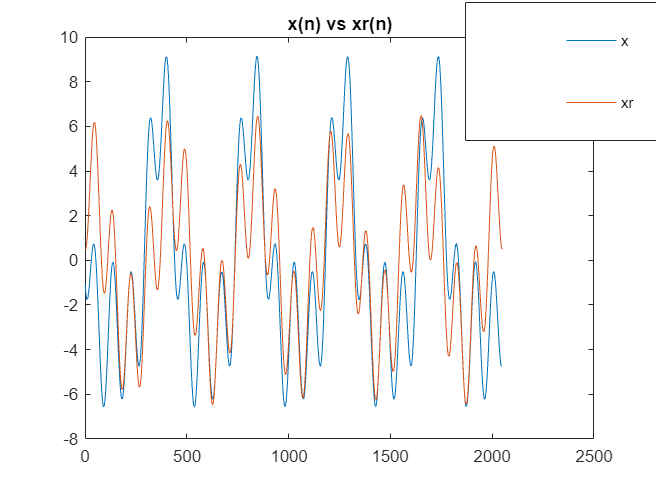


%R1.d
%3 largest peaks of the magnitude
[peaks,index] = maxk(x_abs, 3);
peaks_phase = x_phase(index);
%the frequency is given by the index of the peaks
rec_x = zeros(size(x2));
rec_x(index) = x_FT(index);
rec_x(2048-index+2) = conj(x_FT(index));
xr = ifft(rec_x,2048);

%R1.e
plot(x2,'DisplayName','x');
hold on
plot(xr,'DisplayName','xr');
title('x(n) vs xr(n)');
hold off

legend("Position", [0.72226,0.72433,0.38557,0.26275]);

lgd = legend;

R1.f) The DFT length increase improves frequency resolution, however the three peaks in the magnitude spectrum were already well defined and as such they are not affected by this improvement in frequency resolution, as such there was no difference between the reconstructed signals.  